# MACM 203 Assignment 9

#### Part (a)

Creating a 2×3 random matrix.

T = rand(2,3)

T =     0.9119    0.1314    0.9239
    0.8102    0.7394    0.2220


Now we'll display each element using a single index to see how the elements are accessed sequentially.

for i = 1:6
    disp(['T(' num2str(i) '): ' num2str(T(i))])
end

T(1): 0.91191
T(2): 0.81019
T(3): 0.13144
T(4): 0.73941
T(5): 0.92394
T(6): 0.22197


#### Part (b)

Here we define a function to extract the least significant bit (LSB) from each pixel of a grayscale image, this is where our hidden message is stored, and store them in a new column vector of length h×w (total number of pixels).

function m = extract(D)
    m = reshape(mod(D,2),[],1);
end

#### Part (c)

Now we create a function to embed a secret message into an image by modifying the LSBs of pixels. This alters the image in a way that's typically imperceptible to the human eye.

function D = embed(C,m)
    D = C;
    for k = 1:length(m)
        if mod(C(k),2) ~= m(k)
            if C(k) == 0
                D(k) = 1;
            elseif C(k) == 255
                D(k) = 254;
            else
                D(k) = C(k) + (randi([0 1])*2-1); % Randomly add/subtract 1
            end
        end
    end
end

#### Part (d)

Finding a suitable grayscale image to use as our cover object. We need to confirm it's grayscale with 8-bit depth.

f = 'https://cdn.artphotolimited.com/images/5b9fc1ecac06024957be8806/1000x1000/place-d-espagne-et-fontaine-de-barcaccia.jpg';
imfinfo(f)

ans = struct with fields:
              Filename: 'https://cdn.artphotolimited.com/images/5b9fc1ecac06024957be8806/1000x1000/place-d-espagne-et-fontaine-de-barcaccia.jpg'
           FileModDate: '29-Mar-2025 19:14:21'
              FileSize: 112987
                Format: 'jpg'
         FormatVersion: ''
                 Width: 1000
                Height: 753
              BitDepth: 8
             ColorType: 'grayscale'
       FormatSignature: ''
       NumberOfSamples: 1
          CodingMethod: 'Huffman'
         CodingProcess: 'Progressive'
               Comment: {}
     AutoOrientedWidth: 1000
    AutoOrientedHeight: 753


Loading the image into MATLAB and verifying its *uint8* class.

C = imread(f);
whos C

  Name        Size               Bytes  Class    Attributes

  C         753x1000            753000  uint8              



Displaying the cover image to visualize what we'll be working with.

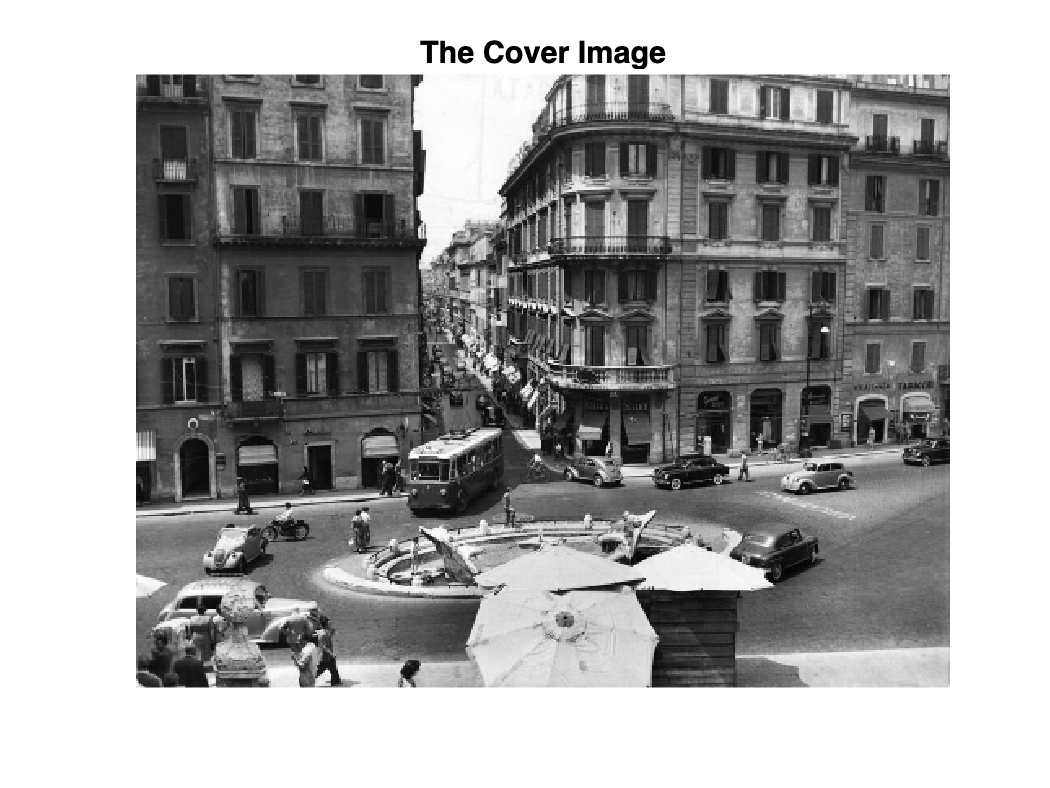

imshow(C)
title('The Cover Image')

#### Part (e)

First, we determine the total number of pixels in our image to know how long our secret message should be.

L = numel(C)

L = 753000

Generating a random binary message of the same length as the number of pixels in our image. This will be our "secret" information.

m = randi([0 1],L,1,'uint8');
m(1:10)

ans = 10x1 uint8 column vector
   1
   1
   0
   1
   1
   1
   1
   0
   0
   1


Checking the distribution of 0s and 1s in our message. Should be approximately 50% if truly random.

sum(m)/L

ans = 0.5001

Embedding our secret message into the cover image using our custom function.

D = embed(C,m);

Displaying the image with our hidden message embedded to see if there are visible changes.

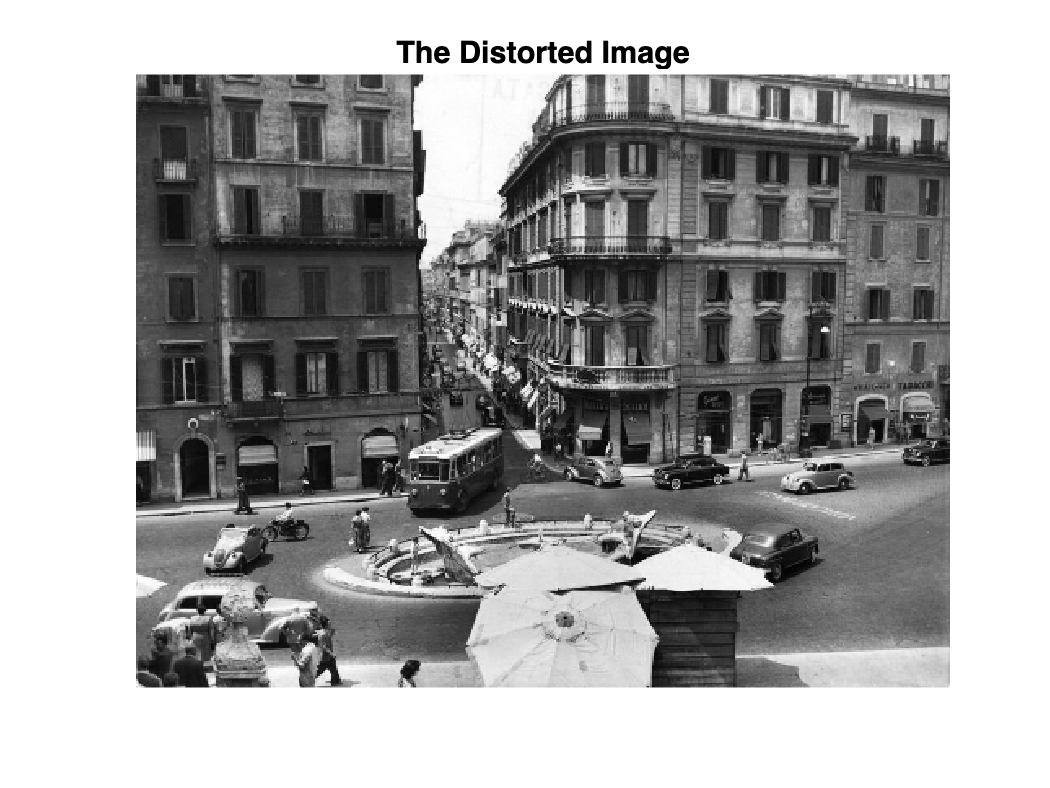

imshow(D)
title('The Distorted Image')

Creating a side-by-side comparison of the original and modified images to observe any visible differences.

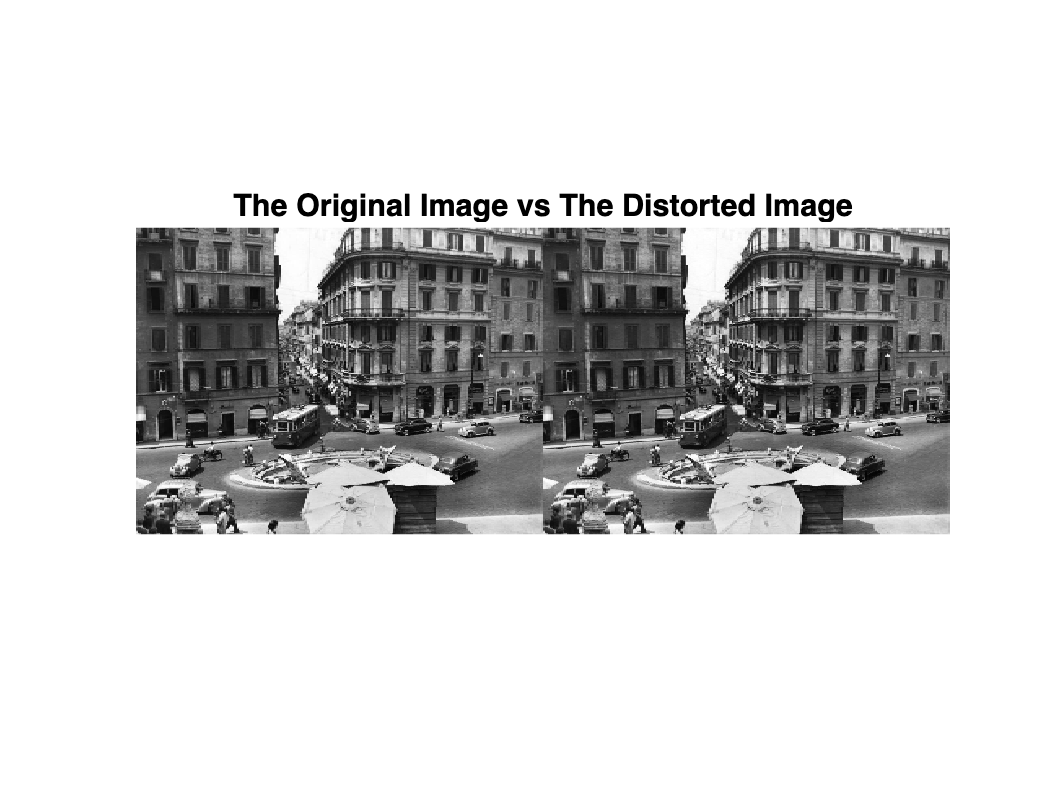

imshowpair(C,D,'montage')
title('The Original Image vs The Distorted Image')

#### Part (f)

Finally, we verify that our embedding and extraction process works correctly by checking if the extracted message matches our original secret message exactly.

sum(extract(D) == m) == L

ans = logical
   1
